# Miniprojekt 4 - Nøjagtig frekvensmåling

## Indledning

Vi vil i denne opgave anvende digital signalbehandling til at lavfiltere et støjfyldt signal indeholdene 40 harmoniske overtoner, som skal illustriere et signal fra en Genset (en motor kombineret af en forbrændingsmotor og elektrisk generator). Efter at signalet er filtreret vil vi gennem zero crossing finde nulgennemgangen af signalet ved samplenummer (sampleinkeks) ved to samples på hver sin side af henholdsvis den positive y-akse og negative y-aske. Herved kan tiden mellem de to samples findes og se om de specifikke opgavebeskrivelses krav opfyldes.

## Formål

Vi vil designe forskellige 2. ordens IIR filtere til filtring af signalet x2 med overtonerene og bruge den bedst engnede til udøvelse af zero crossing til at kunne oplyde kravsspicifikationerne. 

Krav til opgaven, beskriver at både x1 og x2 har en grundfrekvens på 50,1111 Hz

- Afvigelsen må maksimalt være ±10mHz

- Samplingsfrekvensen er 10kHz

## Analyse

## Opgaven

### Tids- og frekvensanalyse

clear;
load('signal_IEC60255_50_1111Hz.mat')
fs = signal.fs; % Samplingfrekvens på 10 kHz
x1 = signal.x1; % Det rene sinus signal
x2 = signal.x2; % Signal med 40 harmoniske overtoner
N = length(x1); % Antal samples
gF = 50.1111;   % Grundfrekvens for begge signaler

Først vil de to signaler blive plottet med en tidsakse i intervallet fra 0 til 55 ms.

Periode tiden findes.

ts = 1/fs; % Sample tid

Nu bestemmes tiden for plottet.

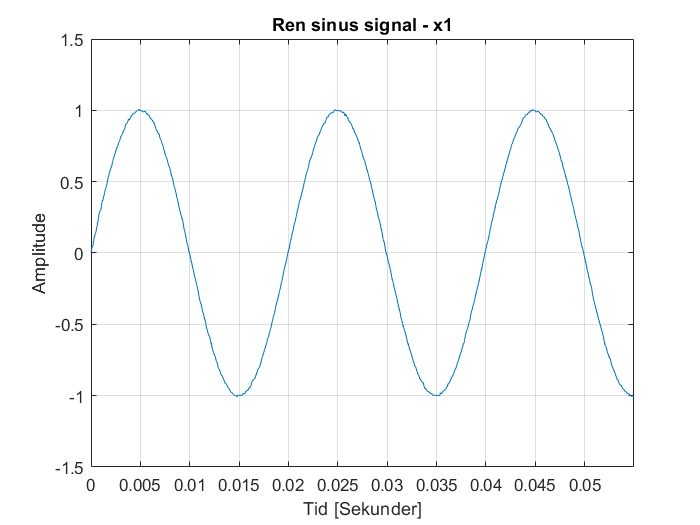

t = 0:ts:(N*ts)-ts; % Varighed i tid
plot(t,x1)          % Plot af Ren sinus signal - x1
xlim([0 0.055])     % Plottes for de første 0.055 sekunder
grid on
title('Ren sinus signal - x1')
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

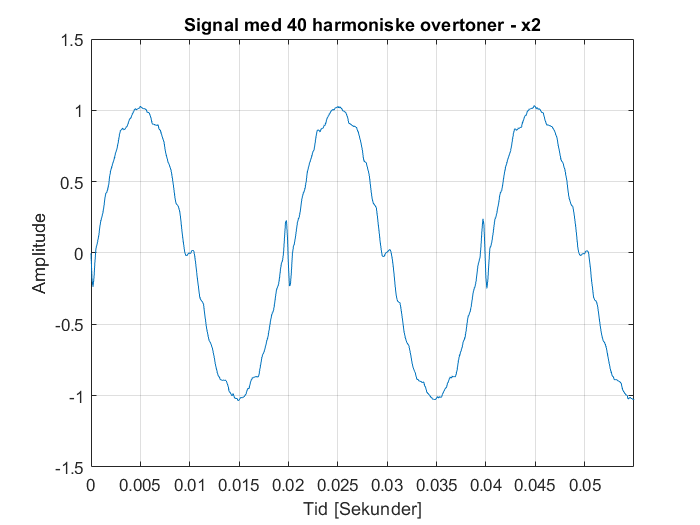

plot(t,x2)      % Plot af signalet med 40 harmoniske overtoner - x2
xlim([0 0.055]) % Plottes for de første 0.055 sekunder
grid on
title('Signal med 40 harmoniske overtoner - x2')
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

Nu beregnes DFT for signalerne, samt plot af amplityde spektrene. Men først vil vi bestemme de nødvendige antal samples, for at opnå en afvielse på maksimalt +- 10mHz. 

delta_f = 0.01;  % Frekvens opløsningen: 0.01 = 10mHz
Nny = fs/delta_f % Minimum antal samples 

Nny = 1000000

Da FFT'en tager sampels med $2^n$, så findes den exponent der er efter 500.000 

Nny = 2^nextpow2(Nny) % Minimum antal samples i n'te potent, fordi FFT bruger n'te potent

Nny = 1048576

DFTx1 = abs(fft(x1,Nny)); % DFT for x1
DFTx2 = abs(fft(x2,Nny)); % DFT for x2
k = 0:Nny-1;              % Frekvens pins
f = k*fs/Nny;             % Frekvensakse

Nu plottes amplitudespektret for både det rene signal og signalet med 40 harmoniske overtoner op til nyquist.

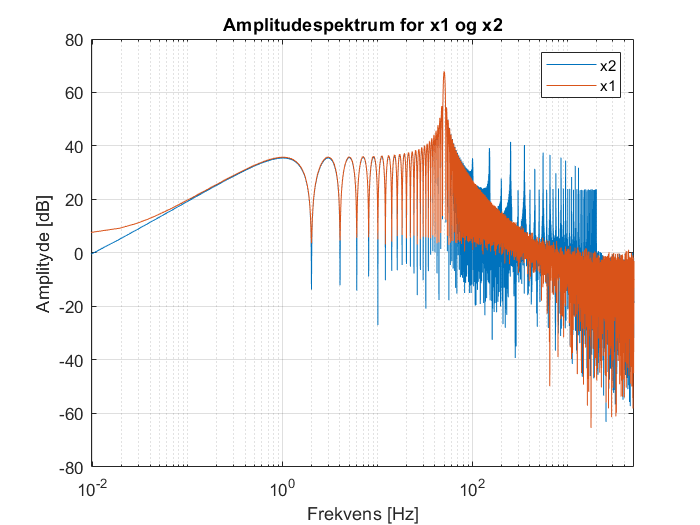

semilogx(f,20*log10(DFTx2)) % Plot af x2 med logaritmisk akse
hold on
semilogx(f,20*log10(DFTx1)) % Plot af x1 med logaritmisk akse
hold off
xlim([0,fs/2]); % x-akse skalering
grid on
title('Amplitudespektrum for x1 og x2')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","x1")

Vi vil nu finde den dominerede frekvens, og herudfra se om vi opfylder kravet om afvielse af frekvensopløsningen

[max_amplitudex2, max_frekvens_binx2] = max(DFTx2(floor(1:end/2))); % Finder max- amplitude og frekvens
max_frekvensx2 = (max_frekvens_binx2/Nny) * fs                      % Finder grundfrekvensen

max_frekvensx2 = 50.1156

afvigelse = (max_frekvensx2-gF) % Afvielse på 0.0045 = 4.5mHz

afvigelse = 0.0045

Det ses ud fra afvigelsen af den kun er 4.5mHz hvilket er minder end 10mHz, som var kravet.

For at finde de harmoniske frekvenskomponenter i signalet x2, plottes amplitudespektret med lineær frekvensakse, for at kunne tælle overtonerne.

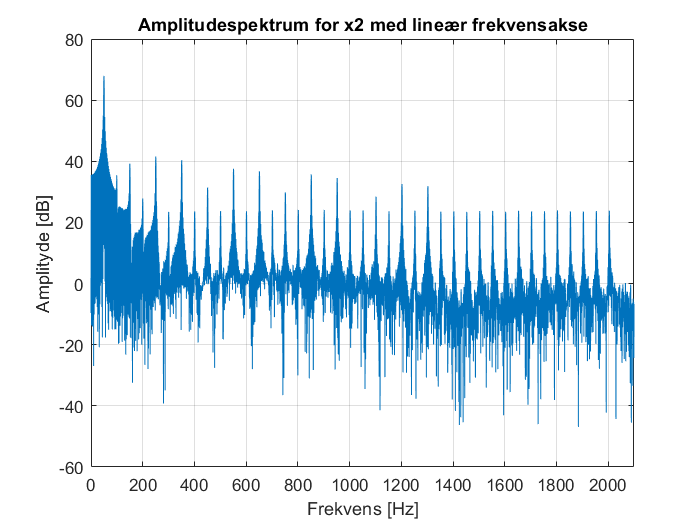

plot(f,20*log10(DFTx2)) % Plot af x2 med lineær akse
grid on
title('Amplitudespektrum for x2 med lineær frekvensakse')
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
xlim([0,2100]); % x-akse skalering

Ud fra plottet ovenfor kan det tælles at der er 40 overtoner. Vi har herved fundet de harmoniske frekvenskomponenter af signalet.

### Hurtig frekvensestimering med zero crossing

#### Filtrering

Nu designes tre forskellige 2. ordens lavpas IIR filtre for at filtre de ikke ønskede højere harmoniske frekvenser fra. Alle filtrene skal have en cut-off til noget højere end den dominerende frekvens.

fc = max_frekvensx2 % Cutoff frekvensen bestemmes til vores beregnede grundfrekvensen

fc = 50.1156

Der startes med Butterworth filtret. 

[butterB,butterA] = butter(2,2*fc/fs,"low"); % B og A koeficienter for Butterworth filtret
%fvtool(butterB,butterA); % Plot af Butterworth filtret

Chebyshev type 1 filteret designes.

[chebyB,chebyA] = cheby1(2,12,2*fc/fs,"low"); % B og A koeficienter for Chebyshev type 1 filtret
%fvtool(chebyB,chebyA); % Plot af Chebyshev type 1 filtret

Chebyshev type 2 filteret designes.

[cheby2B,cheby2A] = cheby2(2,20,2*fc/fs,"low"); % B og A koeficienter for Chebyshev type 2 filtret
%fvtool(cheby2B,cheby2A); % Plot af Chebyshev type 2 filtret

Et eliptisk filtre laves.

[ellipB,ellipA] = ellip(2,1,50,2*fc/fs,"low"); % B og A koeficienter for et eliptisk filtret
%fvtool(ellipB,ellipA); % Plot af eliptisk filtret

Nu påtrykkes signalerne de forskellige filtre.

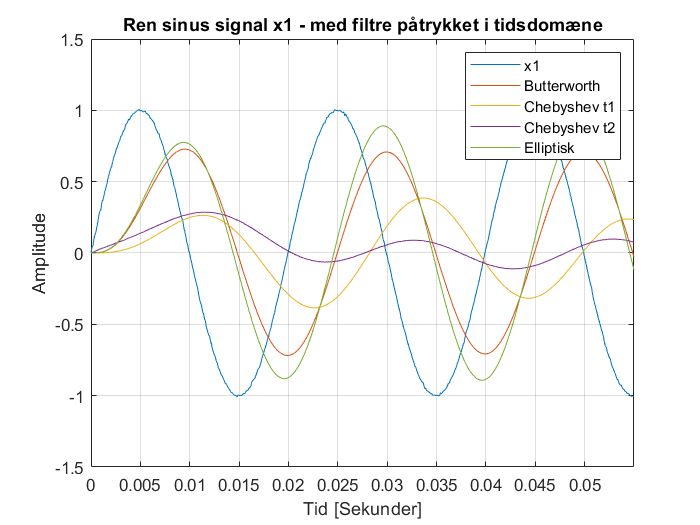

x1butter = filter(butterB,butterA,x1);  % Signal x1 påtrykkes med Butterworth filtret
x1cheby = filter(chebyB,chebyA,x1);     % Signal x1 påtrykkes med Chebyshev type 1 filtret
x1cheby2 = filter(cheby2B,cheby2A,x1);  % Signal x1 påtrykkes med Chebyshev type 2 filtret
x1ellip = filter(ellipB,ellipA,x1);     % Signal x1 påtrykkes med et eliptisk filtret

plot(t,x1,t,x1butter,t,x1cheby,t,x1cheby2,t,x1ellip) % Plot af x1 samt de 4 påtrygte filtre
xlim([0 0.055]) % Plottes for de første 0.055 sekunder
title('Ren sinus signal x1 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

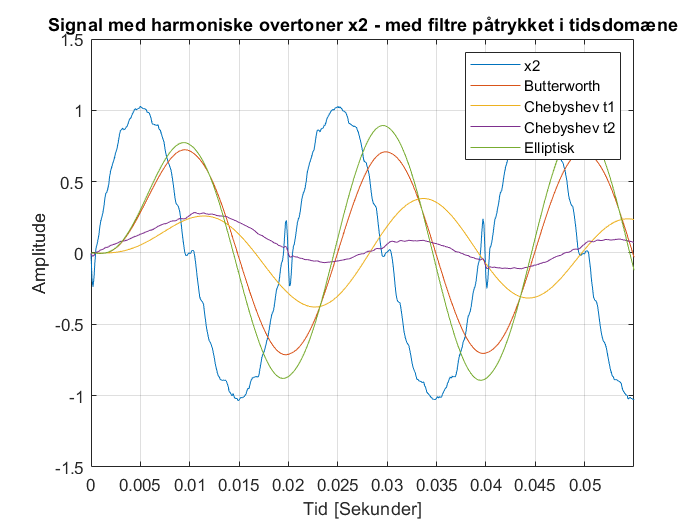

x2butter = filter(butterB,butterA,x2);  % Signal x2 påtrykkes med Butterworth filtret
x2cheby = filter(chebyB,chebyA,x2);     % Signal x2 påtrykkes med Chebyshev type 1 filtret
x2cheby2 = filter(cheby2B,cheby2A,x2);  % Signal x2 påtrykkes med Chebyshev type 2 filtret
x2ellip = filter(ellipB,ellipA,x2);     % Signal x2 påtrykkes med et eliptisk filtret

plot(t,x2,t,x2butter,t,x2cheby,t,x2cheby2,t,x2ellip) % Plot af x2 samt de 4 påtrygte filtre
xlim([0 0.055])                         % Plottes for de første 0.055 sekunder
title('Signal med harmoniske overtoner x2 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

Det ses ud fra overstående plot af de 4 påtrygte filtre på x2 at **Elliptisk** er bedst på den måde at den har filtrere støjet væk, og minimere amplituden mindst muligt. Det ses også at Chebyshev type 2 er dårligt og har stadig støj i signalet.

Amplitudespektret findes ved brug af DFT. Først for x1.

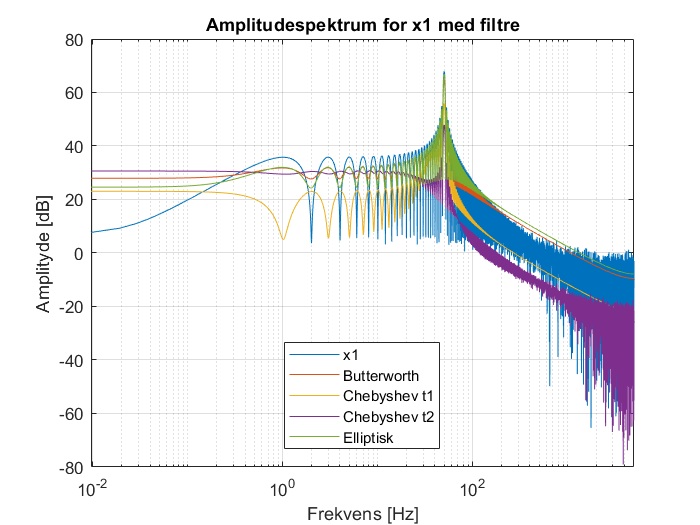

DFTx1butter = abs(fft(x1butter,Nny));   % DFT x1 af Butterworth filtret
DFTx1cheby = abs(fft(x1cheby,Nny));     % DFT x1 af Chebyshev type 1 filtret
DFTx1cheby2 = abs(fft(x1cheby2,Nny));   % DFT x1 af Chebyshev type 2 filtret
DFTx1ellip = abs(fft(x1ellip,Nny));     % DFT x1 af et eliptisk filtret

semilogx(f,20*log10(DFTx1))
hold on
semilogx(f,20*log10(DFTx1butter))       % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx1cheby))        % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx1cheby2))       % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx1ellip))        % Plot af x1 samt de 4 påtrygte filtre
xlim([0,fs/2]);                         % x-akse skalering
hold off
grid on
title('Amplitudespektrum for x1 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

Nu for x2.

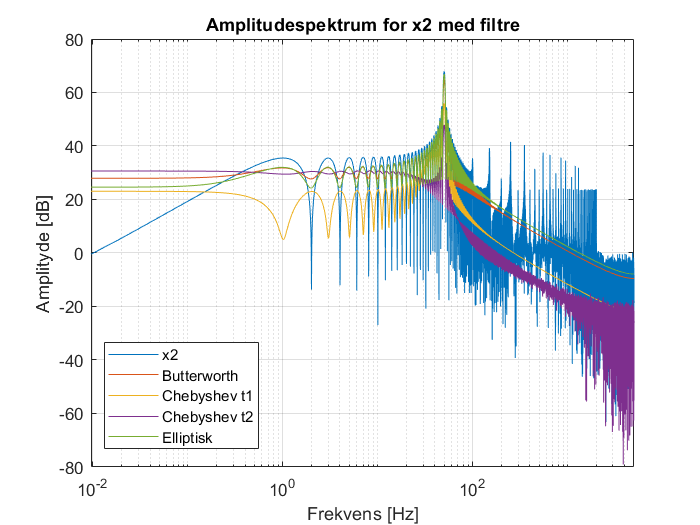

DFTx2butter = abs(fft(x1butter,Nny));    % DFT x1 af Butterworth filtret
DFTx2cheby = abs(fft(x1cheby,Nny));      % DFT x1 af Chebyshev type 1 filtret
DFTx2cheby2 = abs(fft(x1cheby2,Nny));    % DFT x1 af Chebyshev type 2 filtret
DFTx2ellip = abs(fft(x1ellip,Nny));      % DFT x1 af et eliptisk filtret

semilogx(f,20*log10(DFTx2))
hold on
semilogx(f,20*log10(DFTx2butter))       % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx2cheby))        % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx2cheby2))       % Plot af x1 samt de 4 påtrygte filtre
semilogx(f,20*log10(DFTx2ellip))        % Plot af x1 samt de 4 påtrygte filtre
xlim([0,fs/2]);                         % x-akse skalering
hold off
grid on
title('Amplitudespektrum for x2 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

Ud fra amplitudespektret ses også at det elliptiske filter følger signalet x2 bedst og ud fra plottet med den lineær akse var det tydeligt at det filtrere signal godt samt minimere amplituden mindst muligt, hvilket klart er en fordel.

Vi har herved fundet det filter som vi vil arbejde videre med til næste afsnit om Zero crossing algoritme.

#### Zero crossing algoritme